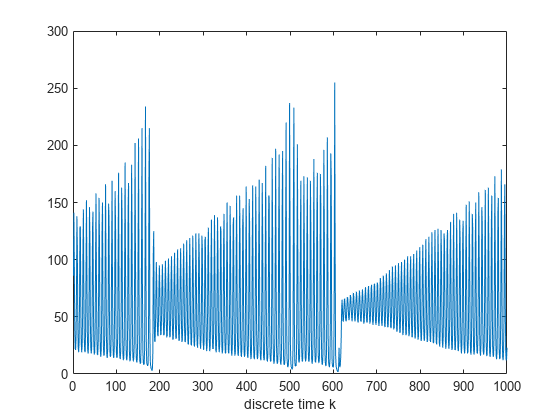

clear all;
close all;

data = load('lasertrain.dat');
testdata = load('laserpred.dat');

mu = mean(data);
sig = std(data);
figure
plot(data)
xlabel("discrete time k")

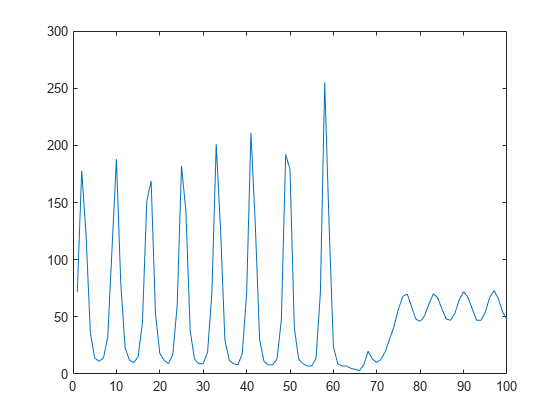

plot(testdata)



numTimeStepsTrain = floor(0.9*numel(data));
data_standard = (data - mu) / sig;

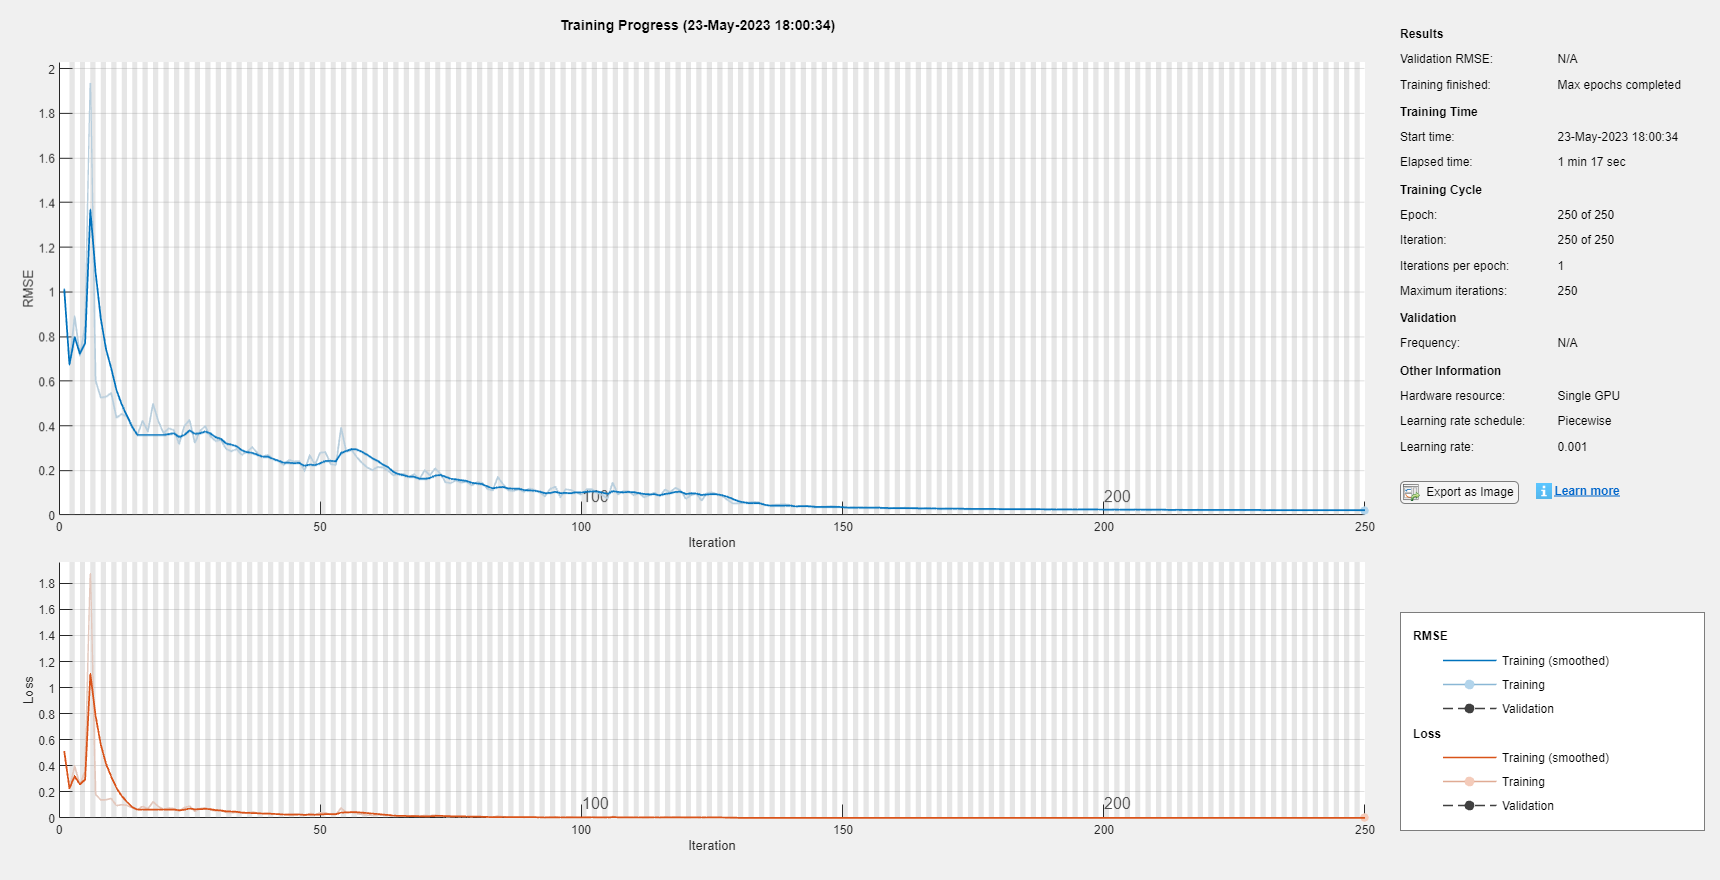

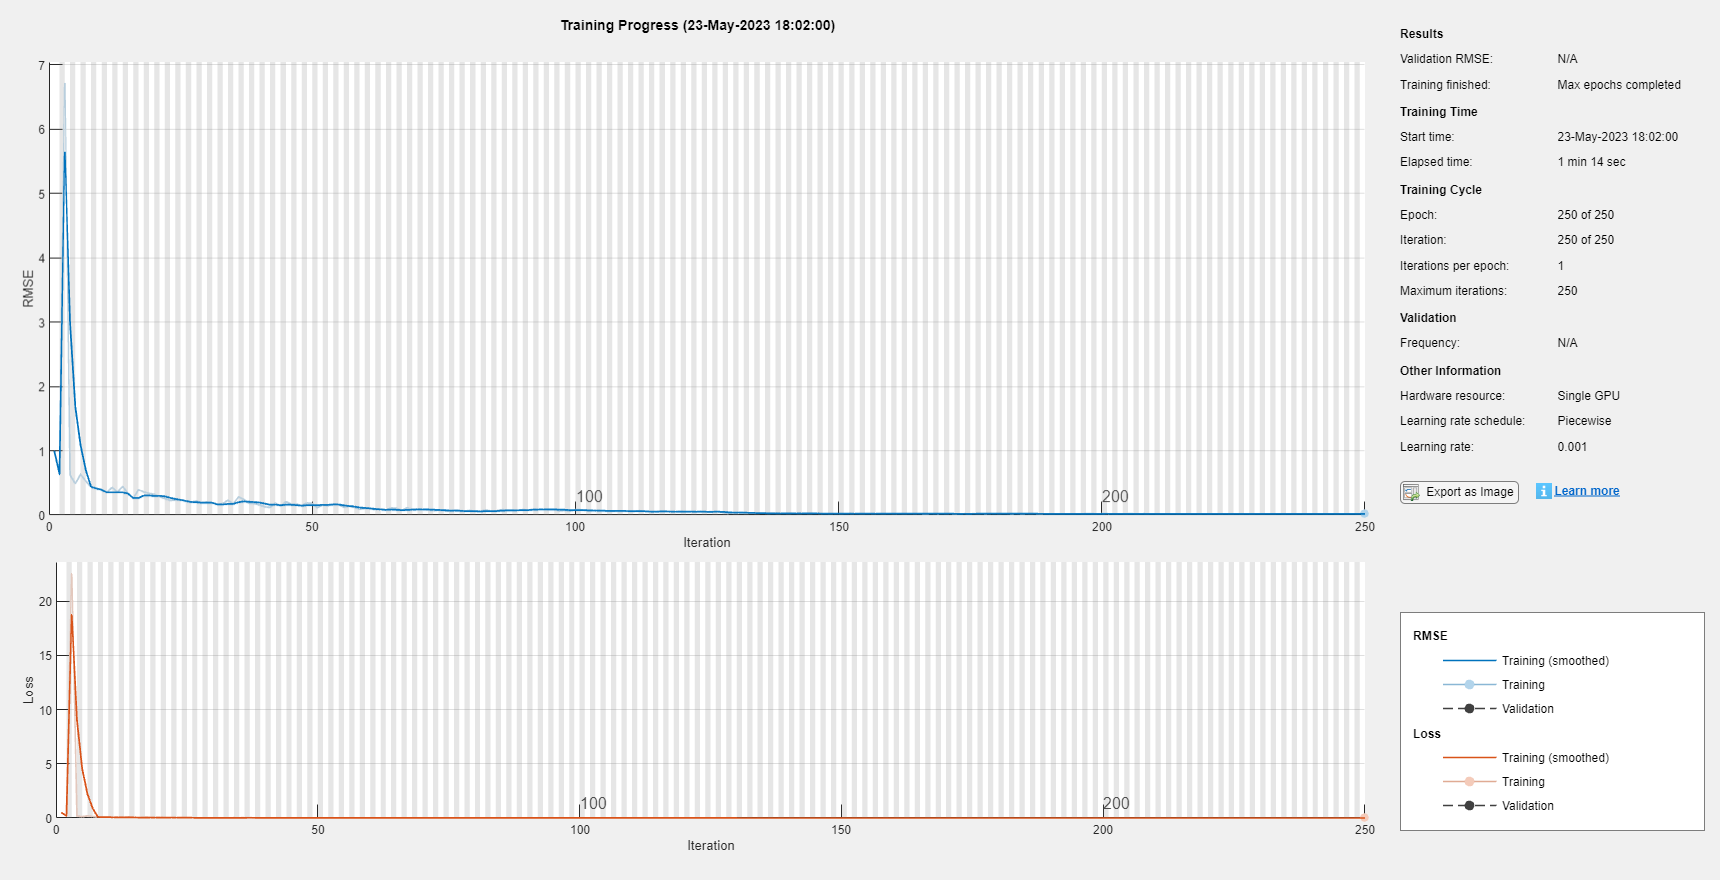

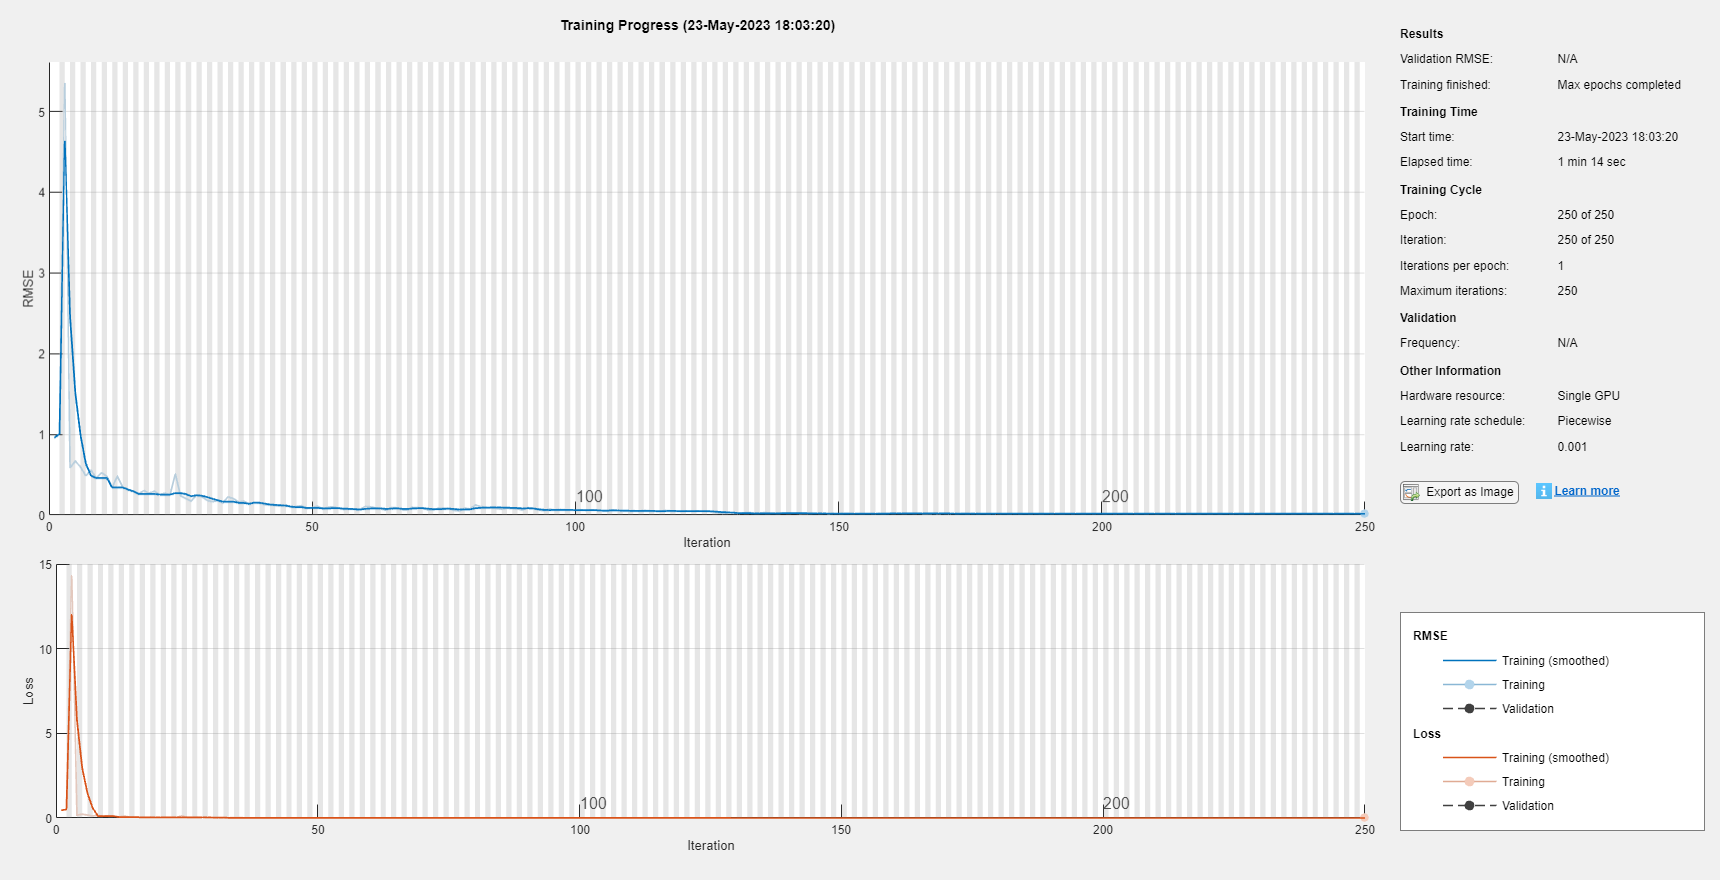

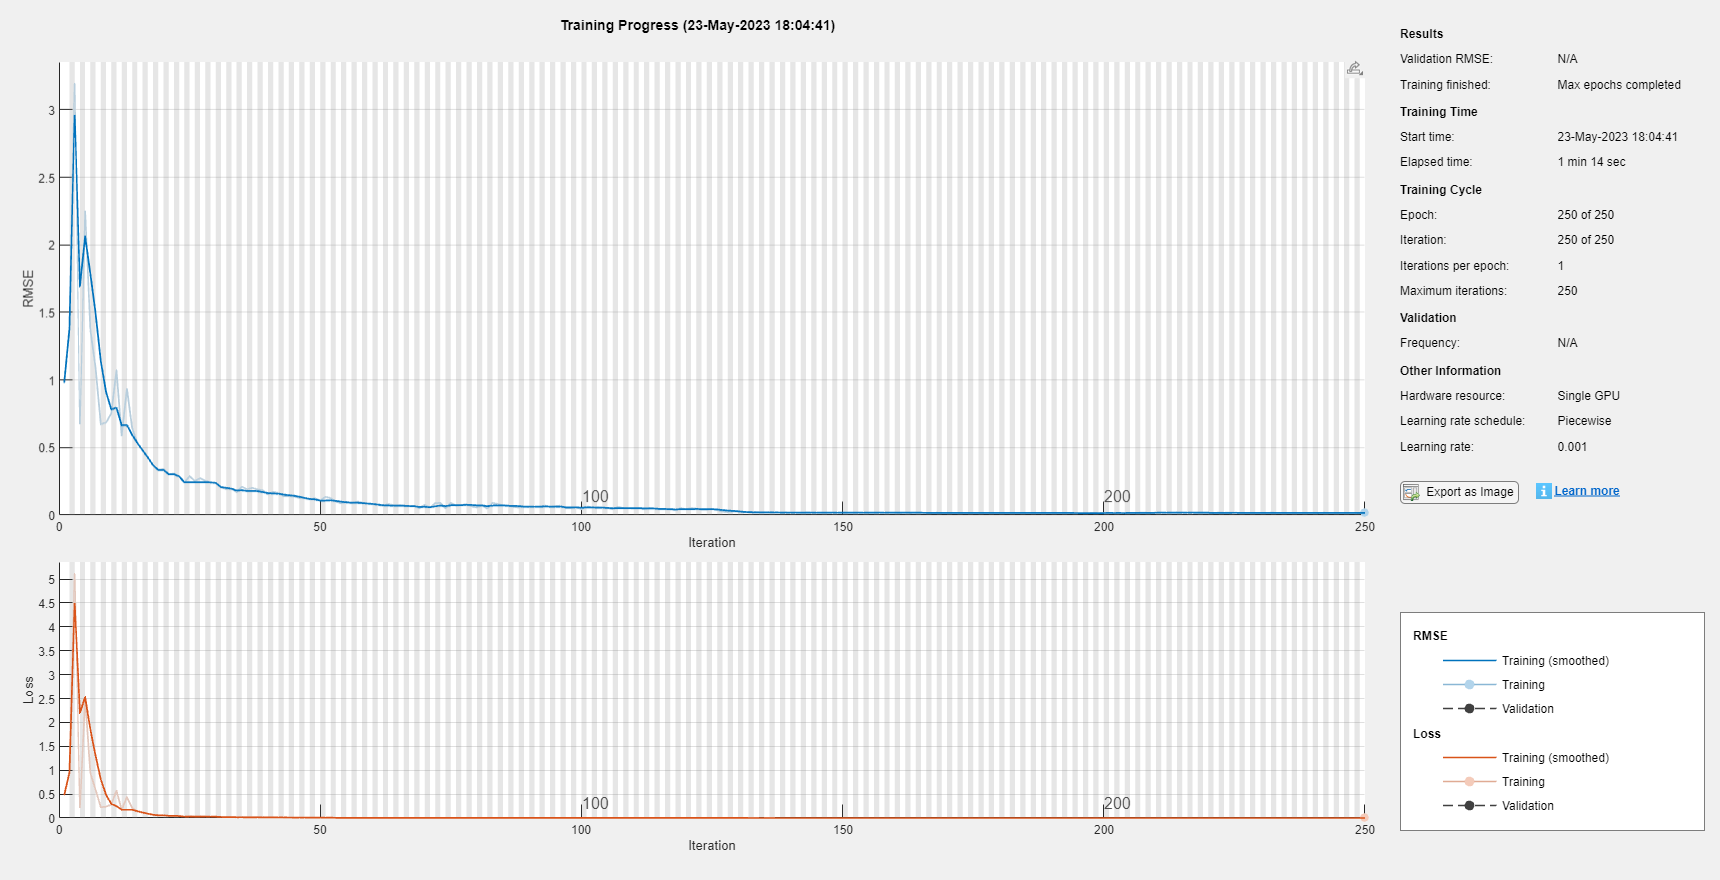

c = 0;

XTrain = data_standard(1:end-1);
YTrain = data_standard(2:end);
YPredMatrix = zeros(4,100);

ls = [5 15 30 50];
for l = ls
    numFeatures = l;
    numResponses = 1;
    numHiddenUnits = 500;
    [Xdata_standard, Ydata_standard] = getTimeSeriesTrainData(data_standard,l);

    layers = [ ...
        sequenceInputLayer(numFeatures)
        lstmLayer(numHiddenUnits)
        fullyConnectedLayer(numResponses)
        regressionLayer];
    
    options = trainingOptions('adam', ...
        'MaxEpochs',250, ...
        'GradientThreshold',1, ...
        'InitialLearnRate',0.005, ...
        'LearnRateSchedule','piecewise', ...
        'LearnRateDropPeriod',125, ...
        'LearnRateDropFactor',0.2, ...
        'Verbose',0, ...
        'Plots','training-progress');
    
    net = trainNetwork(Xdata_standard,Ydata_standard,layers,options);

    
    dataTestStandardized = (testdata - mu) / sig;
    XTest = dataTestStandardized;
    net = predictAndUpdateState(net,Xdata_standard);

    for i = 1:l-1
        YPred(i) = Ydata_standard(end-l+1+i);
    end
    [net,YPred(l)] = predictAndUpdateState(net,Ydata_standard(end-l+1:end)');
    
    numTimeStepsTest = numel(XTest);
    for i = 1+l:numTimeStepsTest+l
        [net,YPred(:,i)] = predictAndUpdateState(net,YPred(i-l:i-1)','ExecutionEnvironment','cpu');
    end

    for i = 1:numTimeStepsTest
        YPred(i) = YPred(i+l-1);
    end
    c = c+1;
    YPredMatrix(c,:) = sig*YPred(1:100) + mu;
    
end


for i = 1:4
    rmse(i) = sqrt(mean((YPredMatrix(i,:)'-testdata).^2))
end

rmse =    38.6731   49.6498   31.1784   12.2308


rmse =    38.6731   49.6498   31.1784   12.2308


rmse =    38.6731   49.6498   31.1784   12.2308


rmse =    38.6731   49.6498   31.1784   12.2308


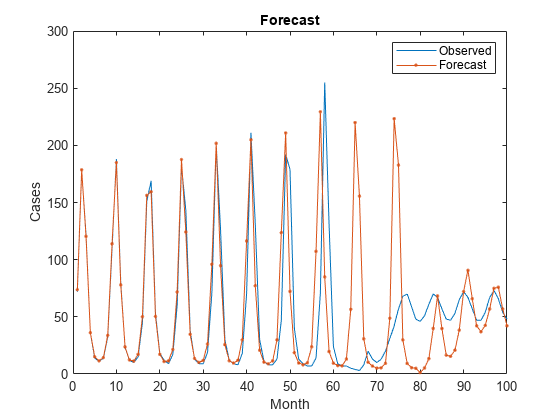

figure
plot(testdata)
hold on
plot(YPredMatrix(2,:),'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])